# Leobardo de Jesús Carbajal

Ejercicios d eestudio para el quiz

- Preparación del entorno

**clear all****:** Borra todas las variables del espacio de trabajo, limpiando cualquier dato almacenado

**close all**: cierra todas las figuras abiertas anteriormente 

**clc**: limpia la ventana de comandos para tener una lista mas limpia

close all
clear all
clc

    2. Definición de la matriz de coordenadas.

**linspace(-5, 5, 10)**. Genera vectores **x** y **y** con 10 puntos linealmente espaciados entre -5 y 5

x = linspace(-5,5,10);
y = linspace(-5,5,10);

    3. Creación de la regilla de coordenadas.

`meshgrid(x, y)`: Crea matrices de coordenadas a partir de los vectores `x` y `y`. Cada elemento de la matriz `x` representa una coordenada x en un plano 2D, y cada elemento de la matriz `y` representa una coordenada **y**.

[x,y] = meshgrid(x,y);

    4. Definición de la sfunciones vectoriales: 

Estas líneas definen las componentes **u** y **v** del campo vectorial. `u` es igual al negativo de `y`, y `v` es igual a `x`. Esto resulta en un campo vectorial que rota en sentido contrario a las agujas del reloj alrededor del origen.

u = cos(x) - y;
v = sin(y) + x;

    5. Graficación del campo vectorial:

`quiver(x, y, u, v)`: Dibuja flechas con componentes `u` y `v` en las posiciones definidas por `x` y `y`. Muestra la dirección y magnitud del campo en cada punto.

quiver(x,y,u,v)

    6. Etiquetado y ajustes gráficos:

- `title`, `xlabel`, `ylabel`: Establecen el título de la gráfica y los nombres de los ejes.

- `xlim`, `ylim`: Definen los límites de los ejes x e y.

title("[cos(x) - y,sin(y) + x]")
xlabel("x")
ylabel("y")
xlim = ([-5,5])

xlim =     -5     5


ylim = ([-5,5])

ylim =     -5     5


    7. Dibujo de los ejes:

- `zeros(size(y))`, `zeros(size(x))`: Genera vectores de ceros del mismo tamaño que `y` y `x` respectivamente, usados para dibujar líneas a lo largo de los ejes.

- `hold on`: Mantiene la gráfica actual para sobreponer más gráficos.

- `plot(y,x1, '-k')`, `plot(x1,y, '-k')`: Dibuja líneas negras en las posiciones de los ejes, representando los ejes x e y.

y1 = zeros(size(y))

y1 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


x1 = zeros(size(x))

x1 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


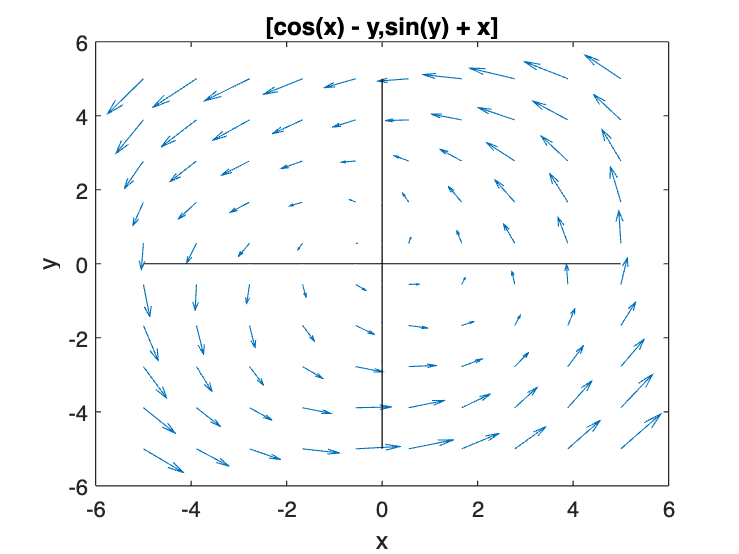


hold on 

plot(y,x1, '-k')
plot(x1, y, '-k')